# **3DOF Robotic Arm**:

# *Kinematics, Motion and Trajectory Planning*

The main objective of this project is to simulate and analyze the kinematics of a 3-degree-of-freedom (3DOF) robotic arm using MATLAB. The focus is on understanding the relationship between joint configurations and the position of the end effector. This simulation involves the following key tasks:

- **Calculation of End Effector Position**: Computing the position of the robotic arm’s end effector based on joint angles and arm configurations.

- **Kinematic Analysis**: Performing forward kinematics to analyze how the joint angles affect the position of the end effector.

- **Trajectory Planning**: Developing and comparing different trajectory methods (cubic and quintic polynomials) to move the arm smoothly from one configuration to another.

- **Inverse Kinematics**: Calculating the necessary joint angles to reach a specific position in space, using inverse kinematics methods.

- **Visualization**: Providing graphical representations of the robotic arm’s movement and trajectory through MATLAB plotting functions.

### System Initialization

In this section, the root path of the project is defined and the necessary function files are added to the MATLAB path for easy access during simulation.

- `pwd`: Retrieves the current working directory (root path of the project).

- `addpath(genpath(...))`: Adds all the subdirectories within the 'functions' folder to the MATLAB search path, making the functions available for use in the script.

% Define the root path of your project
rootPath = pwd;

addpath(genpath(fullfile(rootPath, 'functions')));


### End Effector Position Calculation - Geometrical Model

In this section, the function `EndEffectorPosition` calculates the position of the end effector of a 3-DOF robotic arm based on the provided joint angles (θ1, θ2,θ3) and the translation parameter `d` for one of the joints. The function uses homogeneous transformation matrices to model the robotic arm's kinematics.

#### Rotation Matrices

Rotation matrices are used to describe the rotation of an object in 3D space about the X, Y, and Z axes. The following are the general forms of the rotation matrices:


$$$R_x(\theta) = \left[\matrix{ 1 & 0 & 0 \cr 0 & \cos(\theta) & -\sin(\theta) \cr 0 & \sin(\theta) & \cos(\theta) } \right]$$$
                        
$$$R_y(\theta) = \left[\matrix{ \cos(\theta) & 0 & \sin(\theta) \cr 0 & 1 & 0 \cr -\sin(\theta) & 0 & \cos(\theta) } \right]$$$
                        
$$$R_z(\theta) = \left[\matrix{ \cos(\theta) & -\sin(\theta) & 0 \cr \sin(\theta) & \cos(\theta) & 0 \cr 0 & 0 & 1 } \right]$


$$


#### Homogeneous Transformation Matrices

A homogeneous transformation matrix is used to represent transformations in 3D space, combining both rotation and translation. The general form for a homogeneous transformation matrix is:


$$T = \left[\matrix{ R & t \cr 0 & 1} \right]$$


Where:

- R is one of the rotation matrices ($$R_x(\theta), R_y(\theta), R_z(\theta)$$)

- t is the translation vector, describing the displacement in the 3D space

- The bottom row consists of a vector of zeros (1x3) and a scalar (1) to maintain the matrix’s dimensions (4x4).

The combination of these matrices allows for the calculation of the end effector position and the transformation of various components of the robotic arm. In this case, we have four transformations:

- **Rotation about the X-axis:       **The matrix $T_1^0$ represents a rotation about the X-axis by an angle $$\Theta_1$$, affecting the orientation of the first arm segment.

- **Rotation about the Y-axis:       **The matrix  $T_2^1
$ represents a rotation about the Y-axis by an angle $$\Theta_2
$$, and a translation of 2 units along the X and Z axis (the offset of the second joint).

- **Translation along the Y-axis:   **The matrix $T_3^2$ represents a translation along the Y-axis by a distance ddd, which corresponds to the translation along the second joint.

- **End Effector Transformation:  **Finally, the matrix $T_e^3
$ represents a translation along the X-axis by 2 units, positioning the end effector.


$$$T_1^0 = \left[\matrix{ 1 & 0 & 0 & 0 \cr 0 & \cos(\theta_1) & -\sin(\theta_1) & 0 \cr 0 & \sin(\theta_1) & \cos(\theta_1) & 0 \cr 0 & 0 & 0 & 1 } \right]$$$
                     
$$$T_2^1 = \left[ \matrix{ 
\cos(\theta_2) & 0 & \sin(\theta_2) & -2 \cr
0 & 1 & 0 & 0 \cr
-\sin(\theta_2) & 0 & \cos(\theta_2) & 2 \cr
0 & 0 & 0 & 1
} \right]$$$
                     
$$$T_3^2 = \left[ \matrix{
1 & 0 & 0 & 0 \cr
0 & 1 & 0 & d \cr
0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 1
} \right]$$$
                     
$$$T_e^3 = \left[ \matrix{
1 & 0 & 0 & 2 \cr
0 & 1 & 0 & 0 \cr
0 & 0 & 1 & 0 \cr
0 & 0 & 0 & 1
} \right]$$$


#### Joint Orientations and Transformation Composition

The function calculates the combined transformations for each arm segment, from the base frame to the respective joint frames, and eventually to the end effector. The transformations are combined sequentially:

- Transformation from*** Base*** to ***Joint 2***** (**$T_2^0
$ ): $$T_2^0 = T_1^0 \times T_2^1$$

- Transformation from ***Base*** to ***Joint 3*** ($T_3^0
$):  $$T_3^0 = T_2^0 \times T_3^2$$

- Transformation from ***Base*** to ***End Effector ***($T_e^0
$): $$T_e^0 = T_3^0 \times T_e^3$
$

#### Extraction of Arm Segment Positions and End Effector 

The positions of the arm segments are extracted from the transformation matrices:

- **Arm 1**: Position from $T_1^0
$ and $T_2^0
$

- **Arm 2**: Position from $T_2^0
$ and $T_3^0$

- **Arm 3**: Position from $T_3^0$ and $T_e^0$

The final position of the end effector is extracted from the transformation matrix $T_e^0$: $$p_{\text{Gripper}} = T_e^0(1:3, 4)$$

This is the position of the end effector in global coordinates.

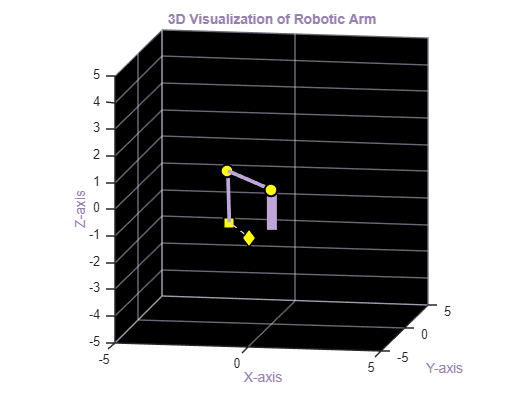

clear;
clf;
clc;

% Calculate end effector position and obtain arm configurations
[pGripper, arm1, arm2, arm3] = EndEffectorPosition(30, 45, 2);

% Plot the robotic arm system
plotSystem(arm1, arm2, arm3, 1);

% Set the view angle for the plot
view(10, 10);

### Kinematic Simulation and Animation 

In this section, the `plotKinematics` function is responsible for simulating the kinematics of the robotic arm and animating its motion between two given joint configurations. The function interpolates the joint angles and calculates the positions of the end effector (gripper) at each time step, visualizing the entire process.

#### Interpolation of Joint Angles

To simulate the movement of the robotic arm, the joint angles (θ1, θ2, θ3) are interpolated between the initial and final values. The function generates 100 time steps between the start and end values of each joint's angles, resulting in a smooth transition from the initial configuration to the final one.

The joint angles are linearly interpolated using the formula:


$$$Q(t) = Q_{\text{start}} + (Q_{\text{end}} - Q_{\text{start}}) \cdot \frac{t}{T}$$$


Where:

- $Q_{start}

$ and $Q_{end}
$ are the initial and final joint angles.

- $t$ is the current time step, and

- $T$is the total animation time (defined as `timeSpan`).

This ensures that the angles progress smoothly from their start values to their end values over the given time span.

#### Calculation of End Effector Position

For each interpolated set of joint angles, the position of the end effector is calculated using the `EndEffectorPosition` function. This is done for each time step, generating the 3D coordinates of the gripper.

End Effector Position Formula:


$$$p_{\text{Gripper}}(t) = \text{EndEffectorPosition}(Q_{1}(t), Q_{2}(t), Q_3(t))$
$$


Where:

- $p_{gripper}(t)$ is the position of the end effector at time $t
$

- The `EndEffectorPosition` function returns the position in the global coordinate frame.

#### Final Trajectory Plot

After the animation is complete, the function generates a plot showing the trajectory of the end effector. The trajectory is a sequence of positions over time:


$$Trajectory(t) = [pGripper(t₁), pGripper(t₂), ..., pGripper(tₙ)]
$$


Where $t_1, t_2, ... t_n$ are the time steps. This plot visualizes the path the end effector follows during the robotic arm's motion.

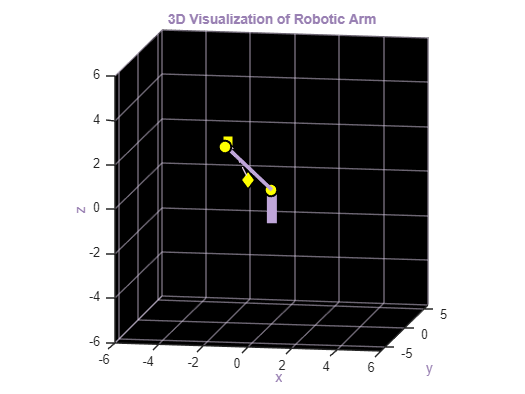

thetaStart = [0, 0, 0];        % Initial angles [Q1_start, Q2_start] in radians
thetaStop = [pi/6, pi, 2];   % Final   angles [Q1_end, Q2_end]     in radians
animationTime = 3;           % Desired animation time in seconds

% Calling the function
plotKinematics(thetaStart, thetaStop, animationTime);

### Modified Joint Angles for Enhanced Trajectory

In this section, the initial and final joint angles are modified to create a more complex and dynamic trajectory. The angles have been set to larger values, resulting in a broader range of motion for the robotic arm. This adjustment provides a more intricate path for the end effector, demonstrating the arm's ability to reach more diverse positions within its workspace. The animation time remains the same to maintain a smooth transition between the start and end configurations.

thetaStart = [-8 * pi, -8 * pi/2, -1];   % Initial angles [Q1_start, Q2_start] in radians
thetaStop  = [8 * pi, 8 * pi/2, 1];      % Final   angles [Q1_end, Q2_end]    in radians
animationTime = 10;                       % Desired animation time in seconds

% Calling the function
plotKinematics(thetaStart, thetaStop, animationTime);

### Trajectory Planning – Function Explanation

In this section, the `trajectoryPlanner` function is responsible for generating and animating the motion of the robotic arm's joints, using two different trajectory planning methods: cubic and quintic polynomials. These methods are employed to interpolate joint positions, velocities, and accelerations over a given time span. The comparison between the two methods is visually shown in separate subplots for position, velocity, and acceleration.

#### Polynomial Trajectory Methods

*Cubic Polynomial Trajectory*

The cubic polynomial trajectory is commonly used for smooth motion between two points. It is defined as a third-degree polynomial that guarantees continuous position, velocity, and acceleration.

The general form of a cubic polynomial is:: 


$$q(t) = a₀ + a₁t + a₂t² + a₃t³$$


To determine the coefficients $a_0, a_1, a_2, a_3$, four constraints are imposed:

- **Initial position**:  $Q(0) = Q_{start}$

- **Initial velocity**: $$\dot{Q}(0) = 0$$

- **Final position**: $Q(T) = Q_{end}$

- **Final velocity**: $$\dot{Q}(T) = 0$$ 

We then apply the following conditions to the cubic polynomial:

- at $t = 0
$: 

$q(0) = a_0 = q_0$, thus $a_0 = q_0$

- Initial velocity condition (at $t = 0$):

$$\dot{q}(0) = a_1 = 0$$, thus $a_1 = 0
$

- Final position condition (at $t = T$): 

$$q(T) = a_0 + a_1 T + a_2 T^2 + a_3 T^3 = q_f$$, substituting $a_1 = 0$


$$$a_2 = -\frac{3a_3 T}{2}$$$


Substituting this expression for $a_2
$ into the equation from the final position condition: $$-\frac{3a_3 T^3}{2} + a_3 T^3 = q_f - q_0$$

Solving for $a_3
$:  $$a_3 = \frac{2(q_f - q_0)}{T^3}$$

The position, velocity, and acceleration are calculated using the following equations:

- **Position:       **$q(t) = a_0 + a_1t + a_2t^2 + a_3t^3$

- **Velocity**:        $\dot{q}(t) = a_1 + 2a_2t + 3a_3t^2$

- **Acceleration**:$\ddot{q}(t) = 2a_2 + 6a_3t$

Quintic Trajectory

The quintic polynomial trajectory is a fifth-degree polynomial that provides even smoother motion by ensuring continuous position, velocity, acceleration, and jerk (rate of change of acceleration). It is especially useful for applications requiring smoother transitions.

Formula for quintic trajectory:


$$q(t) = a_0 + a_1t + a_2t^2 + a_3t^3 + a_4t^4 + a_5t^5$$


Where:

- $q(t)$ is the joint  position at time $t$,

- $a_1, a_2, a_3., a_4, a_5$ are the coefficients determined by boundary conditions (initial and final positions, velocities, and accelerations).

The quintic trajectory is constrained by six conditions:

- 
$$q(0)  = q_0$$


- 
$$\dot{q}(0) = 0 \quad \$$


- 
$$ \ddot{q}(0) = 0 \$$


- 
$$q(T) = q_f \$$


- 
$$\dot{q}(T) = 0 
$$


- 
$$\ddot{q}(T) = 0 
$$


The position, velocity, and acceleration are calculated using the following equations:

- **Position:       **$$q(t) = a_0 + a_1 t + a_2 t^2 + a_3 t^3 + a_4 t^4 + a_5 t^5$$

- **Velocity**:        $\dot{q}(t) = a_1 + 2a_2t + 3a_3t^2 + 4a_4t^3 + 5a_5t^4$

- **Acceleration**:$\ddot{q}(t) = 2a_2 + 6a_3t + 12a_4t^2 + 20a_5t^3
$

From the given function, we can construct a **linear system**:


$$
\left[ \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 1 & 0 & 0 & 0 & 0 \\
0 & 0 & 2 & 0 & 0 & 0 \\
1 & T & T^2 & T^3 & T^4 & T^5 \\
0 & 1 & 2T & 3T^2 & 4T^3 & 5T^4 \\
0 & 0 & 2 & 6T & 12T^2 & 20T^3
\end{array} \right]
\left[ \begin{array}{c}
a_0 \\ a_1 \\ a_2 \\ a_3 \\ a_4 \\ a_5
\end{array} \right] =
\left[ \begin{array}{c}
q_0 \\ 0 \\ 0 \\ q_f \\ 0 \\ 0
\end{array} \right]
\end{equation}$$


This system can be written as:

$A * x = b$,

where: 

- A is the **coefficient matrix**,

- x is the **vector of unknown polynomial coefficients**,

- b is the **vector of constraints**.

#### Trajectory Parameters and Animation

The `jointLimits` matrix defines the initial and final positions for each joint.


$$\texttt{jointLimits} = \left[ \begin{array}{cc}
0 & \frac{\pi}{6} \\
0 & \pi \\
0 & 2
\end{array} \right]$$


Each row corresponds to the initial and final angles for a joint.

- **Total Time and Sampling Points**: The total time (`totalTime`) is the duration for the trajectory, and `samplingPoints` defines the number of points used to generate the trajectory over time.

- **Animation Speed**: The `speed` variable controls the animation speed for the visualization.

jointLimits = [0, pi/6;   % Each row defines the initial and final positions for a joint
                     0, pi  ;    % Format: [initial_position, final_position]
                     0, 2]  ;    

totalTime = 2;  % Total duration of the trajectory (e.g., 10 seconds)
samplingPoints = 100; % Number of sampling points for trajectory generation

% The function generates and compares two trajectory methods:
% - Cubic   polynomial
% - Quintic polynomial
% The differences between these methods will be visibe in the plots
trajectoryPlanner(jointLimits, totalTime, samplingPoints);

### Joint Trajectory Generation and Direct Kinematics

This section focuses on the process of generating joint position (Q), velocity (dQ), and acceleration (ddQ) trajectories, and computing the direct kinematics for a robotic arm using the cubic trajectory method. The cubic polynomial trajectory ensures smooth motion by interpolating the joint positions, velocities, and accelerations over a defined time span.

#### Direct Kinematics

The function `DirectKinematics` computes the velocities of the robotic arm based on the generated joint trajectories. The main steps involved are:

- **Jacobian Matrix**:

For a robotic manipulator with nnn degrees of freedom (DOF), the Jacobian matrix J is an $6 * n
$ matrix that connects the joint velocity vector $\dot{q}$ (where q represents the joint parameters) to the end-effector velocity vector $\dot{x}$ (linear and angular velocities):


$$\dot{x} = J * \dot{q}$$


Where:

- $\dot{{x}} = \left[ \begin{array}{cccccc} \dot{x} & \dot{y} & \dot{z} & \omega_x & \omega_y & \omega_z \end{array} \right]^T$ T is the end-effector velocity vector, containing the linear velocity components $\dot{x}, \dot{y}, \dot{z}$ and angular velocity components $\omega_x, \omega_y, \omega_z$

- $\dot{\mathbf{q}} = \left[ \begin{array}{ccccc}
\dot{q}_1 & \dot{q}_2 & \dots & \dot{q}_n
\end{array} \right]^T$is the joint velocity vector, containing the velocities of the individual joints.

To obtain the Jacobian, differentiate the forward kinematics equation with respect to each joint variable:


$$J = \frac{\partial T}{\partial q_1}, \frac{\partial T}{\partial q_2}, \dots, \frac{\partial T}{\partial q_n}$$


The Jacobian matrix is typically structured as:


$$J = \left[ \begin{array}{cccc}
\frac{\partial x}{\partial q_1} & \frac{\partial x}{\partial q_2} & \cdots & \frac{\partial x}{\partial q_n} \\
\frac{\partial y}{\partial q_1} & \frac{\partial y}{\partial q_2} & \cdots & \frac{\partial y}{\partial q_n} \\
\frac{\partial z}{\partial q_1} & \frac{\partial z}{\partial q_2} & \cdots & \frac{\partial z}{\partial q_n} \\
\frac{\partial \omega_x}{\partial q_1} & \frac{\partial \omega_x}{\partial q_2} & \cdots & \frac{\partial \omega_x}{\partial q_n} \\
\frac{\partial \omega_y}{\partial q_1} & \frac{\partial \omega_y}{\partial q_2} & \cdots & \frac{\partial \omega_y}{\partial q_n} \\
\frac{\partial \omega_z}{\partial q_1} & \frac{\partial \omega_z}{\partial q_2} & \cdots & \frac{\partial \omega_z}{\partial q_n}
\end{array} \right]$$


 The Jacobian matrix relates joint velocities to the linear and angular velocities of the end-effector. It is computed based on the current joint positions $q_1, q_2,q_3
$� and velocities �$\dot{q} _1, \dot{q}_2 , \dot{q} _3$. The Jacobian matrix for the system is:


$$
\text{Jacobian} = \left[ \begin{array}{cccc}
2\sin(q_2)\cos(q_1) - q_3\sin(q_1) - 2\cos(q_1) & 2\sin(q_1)\cos(q_2) & -2\sin(q_2) & 0 \\
q_3\cos(q_1) - 2\sin(q_1) + 2\sin(q_1)\sin(q_2) & -2\cos(q_1)\cos(q_2) & 2\sin(q_1)\cos(q_2) & \cos(q_1) \\
0 & 1 & 0 & 0 \\
0 & 0 & \cos(q_1) & \sin(q_1) \\
0 & 0 & \sin(q_1) & 0
\end{array} \right]
\end{equation}$$


- **Velocity Calculation**: The joint velocities are multiplied by the Jacobian matrix to obtain the linear and angular velocities of the end-effector at each time step. The velocities are stored in a matrix, where the first three rows represent the linear velocities and the last three rows represent the angular velocities.

% Generate joint position (Q), velocity (dQ), and acceleration (ddQ) trajectories
[Q, dQ, ddQ] = CubicTrajectory(jointLimits, totalTime, samplingPoints);

% Define the time vector for the trajectory sampling
time = linspace(0, 2*pi, samplingPoints);

% Compute and plot the direct kinematics based on the joint trajectories
DirectKinematics(Q, dQ, time);

### Inverse Kinematics

This section discusses the inverse kinematics for a 3-DOF robotic arm, where the goal is to compute the joint angles required to move the end-effector from a starting position to a target position in 3D space. In this case, the robotic arm consists of three joints, and we consider the following:

**Parameters**:

-  $l_1, l_2, l_3
$ lenghts of the three rigid segments of the arm.

- $p_{start}$ and $p_
{end}$  represent the initial and target positions of the end-effector, respectively.

**Kinematic Chain**: The robotic arm's kinematics is governed by the angles θ1,θ2,θ3, which correspond to the rotations at the joints. These angles must be determined to position the end-effector at the target point $p_{end}$.

p_start = [2.2; 2; 0]; 
p_end   = [1; 1; 1];    

animationTime = 1; 
f = 1;
plotInverseKinematics(p_start, p_end, animationTime, f);